# **Linear MATLAB Material in a Cyclic Zero-Length Pushover**

This notebook-style example places a callback-backed linear material inside a regular OpenSees zeroLength element. 

A standard cyclic displacement pushover history is imposed at the free node and the material response is recovered from the Element.

The model is deliberately small, but it uses the complete OpenSees analysis stack. 

```text

  fixed node 1 ---- zeroLength + MATLAB material ---- node 2

                                                                  --> u(t)

```

For a zeroLength element, material strain is the relative deformation and material stress is the corresponding resisting force.

The exact response is

$$

F(t)=K u(t)

$$

clc; clear; close all;

### Create the OpenSees command interface

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;
ops.wipe();

### Define the material and cyclic pushover protocol

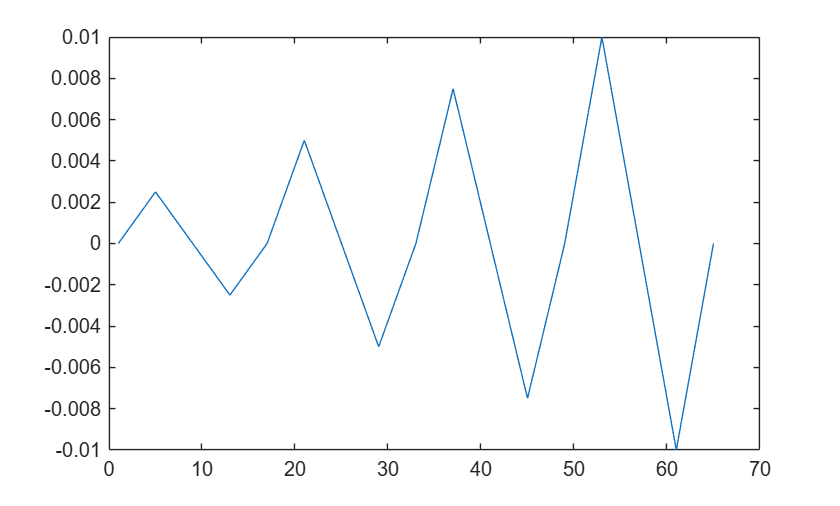

% The protocol uses progressively increasing displacement amplitudes. At every
% amplitude level, the controlled node follows
%
%   0 -> +peak -> -peak -> 0
%
% with linear subdivisions along each branch. This is a conventional cyclic
% pushover history rather than a sinusoidal excitation.

K = 1000.0;                  % Force per unit deformation
materialTag = 1;
elementTag = 1;
timeSeriesTag = 1;
patternTag = 1;

cyclicAmplitudes = [0.0025, 0.0050, 0.0075, 0.0100];
incrementsPerPositiveLeg = 4;
targetDisplacement = buildCyclicProtocol( ...
    cyclicAmplitudes, incrementsPerPositiveLeg);

figure("Color", "w");
plot(targetDisplacement);

### Build the one-dimensional zero-length model

% Both nodes have the same coordinate because the element deformation is the
% relative nodal displacement. Node 1 is fixed, and node 2 receives the
% cyclic pushover displacement defined later.

ops.model("basic", "-ndm", 1, "-ndf", 1);
ops.node(1, 0.0);
ops.node(2, 0.0);
ops.fix(1, 1);


initialState = struct( ...
    "K", K, ...
    "trialCount", 0);

ops.uniaxialMaterial( ...
    "MatlabUniaxialMaterial", ...
    materialTag, ...
    @linearMaterialCallback, ...
    initialState, ...
    K);

% zeroLength obtains its own copy of the material. The copied material keeps
% independent trial and committed states while sharing the callback function.
ops.element("zeroLength", elementTag, 1, 2, ...
    "-mat", materialTag, "-dir", 1);


### Define the reference load for displacement control

% DisplacementControl needs a nonzero reference load vector to form the static
% equilibrium equations. Its magnitude does not prescribe the actual force;
% OpenSees solves for the load factor required to reach each displacement.

ops.timeSeries("Linear", timeSeriesTag);
ops.pattern("Plain", patternTag, timeSeriesTag);
ops.load(2, 1.0);


### Configure and run the static analysis

% Although this material is linear, Newton is used so the setup is identical
% to the nonlinear tutorial.

ops.constraints("Plain");
ops.numberer("Plain");
ops.system("BandGeneral");
ops.test("NormDispIncr", 1.0e-8, 10, 0);
ops.algorithm("Newton");

displacementIncrement = diff(targetDisplacement);
firstIncrement = displacementIncrement(1);
ops.integrator("DisplacementControl", 2, 1, firstIncrement, ...
    1, firstIncrement, firstIncrement);
ops.analysis("Static");

numberOfSteps = numel(targetDisplacement) - 1;
deformation = zeros(numberOfSteps + 1, 1);
force = zeros(numberOfSteps + 1, 1);

% The initial state at pseudo-time zero is known exactly.
deformation(1) = ops.nodeDisp(2, 1) - ops.nodeDisp(1, 1);
force(1) = ops.eleResponse(elementTag, "material", 1, "stress");

for step = 1:numberOfSteps
    % Convert consecutive cyclic-pushover targets into controlled increments.
    % Replacing the integrator permits positive and negative increments in one
    % continuous cyclic analysis.
    if step > 1
        increment = displacementIncrement(step);
        ops.integrator("DisplacementControl", ...
            2, 1, increment, 1, increment, increment);
    end
    status = ops.analyze(1);
    assert(status == 0, "OpenSees failed at cyclic pushover step %d.", step);

    deformation(step + 1) = ...
        ops.nodeDisp(2, 1) - ops.nodeDisp(1, 1);
    force(step + 1) = ...
        ops.eleResponse(elementTag, "material", 1, "stress");

    assert(abs(deformation(step + 1) - targetDisplacement(step + 1)) ...
        < 1.0e-10, ...
        "DisplacementControl did not reach the target at step %d.", step);
end


### Verify equilibrium and the constitutive response

% Evaluate the same callback directly in MATLAB. This independent driver
% commits the returned state after every target point, matching a sequence of
% converged OpenSees steps without using an Element or analysis algorithm.
[matlabForce, ~] = evaluateCallbackHistory( ...
    @linearMaterialCallback, targetDisplacement, initialState);

assert(max(abs(deformation - targetDisplacement)) < 1.0e-10);
assert(max(abs(force - matlabForce)) < 1.0e-9 * max(1.0, max(abs(force))));


### Plot the material force-deformation curve

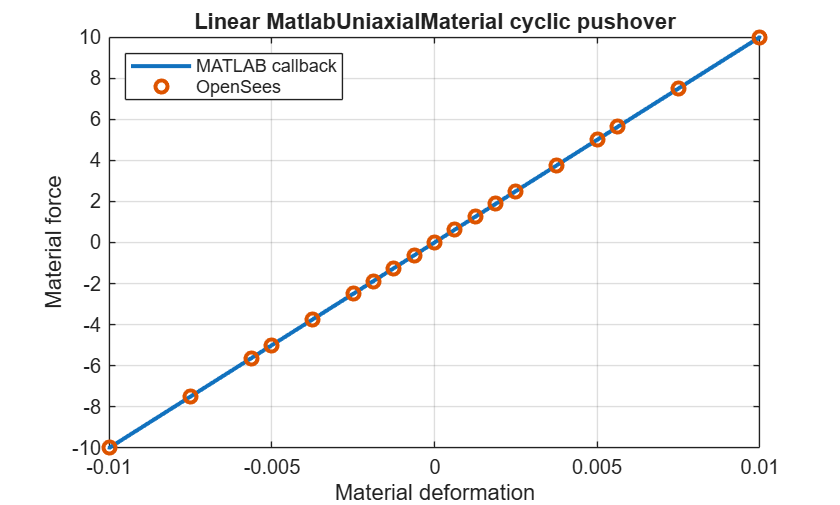

% No figure is written to disk. Repeated displacement cycles trace the same
% straight line because a linear material has no path-dependent history.

figure("Color", "w");
plot(targetDisplacement, matlabForce, "-", "LineWidth", 2, ...
    "DisplayName", "MATLAB callback");
hold on;
plot(deformation, force, "o", "MarkerSize", 6, 'LineWidth',2, ...
    "DisplayName", "OpenSees");
grid on;
xlabel("Material deformation");
ylabel("Material force");
title("Linear MatlabUniaxialMaterial cyclic pushover");
legend("Location", "northwest");

ops.wipe();

### Cyclic displacement protocol helper

% Each amplitude contains three linear branches: zero to positive peak,
% positive peak to negative peak, and negative peak back to zero. The middle
% branch uses twice as many increments because it spans twice the displacement.

function protocol = buildCyclicProtocol(amplitudes, incrementsPerPositiveLeg)
    protocol = 0.0;
    
    for amplitude = amplitudes
        positiveBranch = linspace(0.0, amplitude, ...
            incrementsPerPositiveLeg + 1).';
        reversalBranch = linspace(amplitude, -amplitude, ...
            2*incrementsPerPositiveLeg + 1).';
        returnBranch = linspace(-amplitude, 0.0, ...
            incrementsPerPositiveLeg + 1).';
    
        protocol = [protocol; ... %#ok<AGROW>
            positiveBranch(2:end); ...
            reversalBranch(2:end); ...
            returnBranch(2:end)];
    end
end


### Direct MATLAB callback driver

% This helper is intentionally independent of OpenSees. It supplies each target
% deformation to the callback and treats the returned trial state as committed
% before advancing to the next point.

function [force, tangent] = evaluateCallbackHistory(callback, deformation, initialState)
    numberOfPoints = numel(deformation);
    force = zeros(numberOfPoints, 1);
    tangent = zeros(numberOfPoints, 1);
    committedState = initialState;
    
    for point = 1:numberOfPoints
        action = "trial";
        if point == 1
            action = "init";
        end
        trial = struct("strain", deformation(point), "strainRate", 0.0);
        [response, trialState, status] = callback(action, trial, committedState);
        assert(status == 0, "Direct MATLAB callback evaluation failed.");
        force(point) = response.stress;
        tangent(point) = response.tangent;
        committedState = trialState;
    end
end


### MATLAB material callback

% Every trial evaluation must be a pure calculation from committedState and
% the current trial input. This rule remains important even for this simple
% model because OpenSees may evaluate a material several times within one step.

function [response, state, status] = linearMaterialCallback(action, trial, committedState)
    state = committedState;
    status = 0;
    
    response = struct( ...
        "stress", committedState.K * trial.strain, ...
        "tangent", committedState.K);
    
    switch action
        case "init"
            state.trialCount = 0;
    
        case "trial"
            state.trialCount = committedState.trialCount + 1;
    
        otherwise
            % Current OpenSeesMEX versions invoke only init and trial. Commit,
            % rollback, reset, and destruction are local C++ state operations.
            status = -1;
    end
end
